# Iterative Detection and Decoding for Multiuser Systems Based on MMSE Refinements With Active or Passive RIS

### Template Script

**Author:** Roberto Câmara (camara2k@gmail.com/ camara@ime.eb.br)

**Date:** First Semester/2024

### Introduction to the Code: 

This MATLAB script supports the results presented in the paper:

*Iterative Detection and Decoding for Multiuser Systems Based on MMSE Refinements with Active or Passive RIS*

Available at: [https://ieeexplore.ieee.org/document/10747209](https://ieeexplore.ieee.org/document/10747209)

An iterative detection and decoding (IDD) scheme is proposed for multiuser multiple-antenna systems assisted by an active or a passive Reconfigurable Intelligent Surface (RIS). The proposed approach features an IDD strategy that incorporates Low-Density Parity-Check (LDPC) codes, RIS processing with refinements of soft information in the form of log likelihood ratios (LLRs) and truncation. Specifically, a minimum mean square error (MMSE) receive filter is used for refinement of LLRs and truncation at the RIS, and for soft interference cancellation at the receiver. An analysis of the proposed MMSE refinement is also devised along with a study of the computational complexity of the proposed and existing schemes. Simulation results demonstrate significant improvements in system capacity and bit error rate in the presence of block-fading channels.

### Summary of the algorithm:

The key steps in the algorithm are:

- **Variables: **Are in the script initializeSystem_WCL1.mlx. 

- **Pw_user_dBm and Packets: **Represent the user power levels (PWR) and the number of packets simulated for each PWR value. *(Note: These vectors must have the same size.)*

- **Methods**: Specify the methods to be evaluated.

- **Channel Generation:** For each iteration, the `generateRayleigh` function creates channel coefficients stored in the struct variable `channel`.

- **Channel Estimation:** The `CE_PRIS_CONV` function estimates the channel based on the coefficients and updates the `channel` struct variable.

- **Results Plotting:** The `generatePlots4` function checks which methods are active (not commented out) and generates the corresponding plots.

#### Key Features of this Code:

- **Result Tracking:** For each SNR value, results are saved in the file `wcl01.mat`, allowing real-time monitoring of simulation progress.

- **Parallel Computing:** Supports parallel looping for faster simulations.

- **Custom Configurations:** Users can comment out unneeded methods (e.g., `MMSE_WORIS()`) to focus on specific evaluations. The plotting function adapts automatically to the active methods.

- **Flexible Packet Settings:** Allows different numbers of packets for each SNR value.

#### Observation:

- Ideal number of Packets: 1500~2000. (at least).

- For Sum-Rate only consider the perfect CSI.

### Define if the process will involve parallel looping or not.

clear; close all; clc
% Define if the simulation will be run in parallel-------------------------------
% It is also needed to manually change the inner loop 'for' to 'parfor'!
useParallel = true;
% Progress bar ------------------------------------------------------------------
if ~useParallel
    f = waitbar(0, 'Starting');
end

### Setup variables

format long
warning('on')

% Simulation (defined by the user) --------------------------------------------------------------
Pw_user_dBm = (4:11);                         % Power per user in dBm
Packets = [500 500 500 1000 1000 1500 2000 2500];   % Number of Packets to Send (for each value of Pw_user_dBm)

if length(Packets) ~= length(Pw_user_dBm)
   error('Error Packets and Pw_user_dBm vectors must have the same size')
end

% System Initialization
[sys,enviroment,estimation,idd1,idd3] = initializeSystem_WCL1(Pw_user_dBm);

% Methods Evaluated in Simulation ---------------------------------------------------------------
methods = [ 
            "MMSE W/O RIS Perfect CSI";
            "MMSE W/O RIS Estimated CSI";
            "Passive RIS Perfect CSI";
            "Passive RIS Estimated CSI";
            "IDD (1) MMSE W/O RIS Perfect CSI";
            "IDD (1) MMSE W/O RIS Estimated CSI";
            "IDD (3) MMSE W/O RIS Perfect CSI";
            "IDD (3) MMSE W/O RIS Estimated CSI";
            "IDD (1) Passive RIS Perfect CSI";
            "IDD (1) Passive RIS Estimated CSI";
            "IDD (3) Passive RIS Perfect CSI";
            "IDD (3) Passive RIS Estimated CSI";
          ];

% Auxiliar variables ---------------------------------------------------------------------------
PacketBitLength = sys.PacketDataLength*sys.n_tx;
DataLength = (sys.PacketDataLength-estimation.T0_min*sys.M_ORD)*sys.n_tx;
numberofmethods = length(methods);
numPWR = length(Pw_user_dBm);        
DateI = datetime('now');

% Variables Initialization----------------------------------------------------------------------
RsumVec = zeros(numberofmethods,numPWR);
BerVec  = zeros(numberofmethods,numPWR);

### **Main Function **

for pwr = 1:numPWR
    printStatus(pwr,Pw_user_dBm)
    % Auxiliar variables in the loop ------------------------------
    RsumVec_aux = zeros(numberofmethods,length(Packets));
    BerVec_aux = zeros(numberofmethods, length(Packets));

    parfor NumPackets = 1:Packets(pwr)
        % init variables ------------------------------------------
        Ber = zeros(length(methods),1);
        Rsum = zeros(length(methods),1);

        % Channel coefficients generation ----------------------------------------------------------------------------
        channel = generateRayleight(sys,enviroment,'weak');
       
        % Estimation ----------------------------------------------------------------------------
        channel = CE_PRIS_CONV(sys, channel, estimation, 'with_noise','without_noise', pwr);

        % MMSE W/O RIS Perfect CSI----------------------------------------------------------------------------------------------
        [bErrors, Rsum_aux] = MMSE_WORIS(sys, channel, 'perfectcsi', pwr);
        Ber(1) = bErrors/(PacketBitLength);
        Rsum(1) = Rsum_aux;
        % % MMSE W/O RIS EStimated CSI -------------------------------------------------------------------------------------------
        % [bErrors, Rsum_aux] = MMSE_WORIS(sys, channel, 'estimated', pwr);
        % Ber(2) = bErrors/(PacketBitLength);
        % Rsum(2) = Rsum_aux;
        % % Passive RIS Perfect CSI----------------------------------------------------------------------------------------------
        % [bErrors, Rsum_aux] = MMSE_PRIS_DIAG(sys, channel, 'perfectcsi', pwr);
        % Ber(3) = bErrors/(PacketBitLength);
        % Rsum(3) = Rsum_aux;
        % % Passive RIS Estimated CSI -------------------------------------------------------------------------------------------
        % [bErrors, Rsum_aux] = MMSE_PRIS_DIAG(sys, channel, 'estimated', pwr);
        % Ber(4) = bErrors/(PacketBitLength);
        % Rsum(4) = Rsum_aux;
        % % IDD (1) W/O RIS Perfect CSI----------------------------------------------------------------------------------------------
        % [bErrors, Rsum_aux] = IDD_MMSE_WORIS(sys, channel, idd1, 'perfectcsi', pwr);
        % Ber(5) = bErrors/(PacketBitLength);
        % Rsum(5) = Rsum_aux;
        % % IDD (1) W/O RIS Estimated CSI -------------------------------------------------------------------------------------------
        % [bErrors, Rsum_aux] = IDD_MMSE_WORIS(sys, channel, idd1, 'estimated', pwr);
        % Ber(6) = bErrors/(PacketBitLength);
        % Rsum(6) = Rsum_aux;
        % % IDD (3) W/O RIS Perfect CSI----------------------------------------------------------------------------------------------
        % [bErrors, Rsum_aux] = IDD_MMSE_WORIS(sys, channel, idd3, 'perfectcsi', pwr);
        % Ber(7) = bErrors/(PacketBitLength);
        % Rsum(7) = Rsum_aux;
        % % IDD (3) W/O RIS Estimated CSI -------------------------------------------------------------------------------------------
        % [bErrors, Rsum_aux] = IDD_MMSE_WORIS(sys, channel, idd3, 'estimated', pwr);
        % Ber(8) = bErrors/(PacketBitLength);
        % Rsum(8) = Rsum_aux;
        % % IDD (1) Passive RIS Perfect CSI----------------------------------------------------------------------------------------------
        % [bErrors, Rsum_aux] = IDD_MMSE_PRIS(sys, channel, idd1, 'perfectcsi', pwr);
        % Ber(9) = bErrors/(PacketBitLength);
        % Rsum(9) = Rsum_aux;
        % % IDD (1) Passive RIS Estimated CSI -------------------------------------------------------------------------------------------
        % [bErrors, Rsum_aux] = IDD_MMSE_PRIS(sys, channel, idd1, 'estimated', pwr);
        % Ber(10) = bErrors/(PacketBitLength);
        % Rsum(10) = Rsum_aux;
        % % IDD (3) Passive RIS Perfect CSI----------------------------------------------------------------------------------------------
        % [bErrors, Rsum_aux] = IDD_MMSE_PRIS(sys, channel, idd3, 'perfectcsi', pwr);
        % Ber(11) = bErrors/(PacketBitLength);
        % Rsum(11) = Rsum_aux;
        % % IDD (3) Passive RIS Estimated CSI -------------------------------------------------------------------------------------------
        % [bErrors, Rsum_aux] = IDD_MMSE_PRIS(sys, channel, idd3, 'estimated', pwr);
        % Ber(12) = bErrors/(PacketBitLength);
        % Rsum(12) = Rsum_aux;
       
        % %Ber and Sum-rate Matrix generation
        BerVec_aux(:,NumPackets)    = Ber;
        RsumVec_aux(:,NumPackets)   = Rsum;

        % Wait bar -----------------------------------------------------------------
        if ~useParallel
            aux = ((pwr-1)*Packets)+NumPackets;
            waitbar(aux/(numPWR*Packets), f, sprintf('Progress: %d %%', floor(aux*100/(numPWR*Packets))   ));
        end
    end    
    % update ber and Rsum vector ----------------------------------------------------
    BerVec(:,pwr) = mean(BerVec_aux,2);
    RsumVec(:,pwr) = mean(RsumVec_aux,2);

    % time tracking -----------------------------------------------------------------
    Date = datetime('now');
    Dur = Date-DateI;

    % automatic saving per iteration ------------------------------------------------
    if useParallel
       save('data/main.mat');
    end
end

SNR:    11

### **Plots**

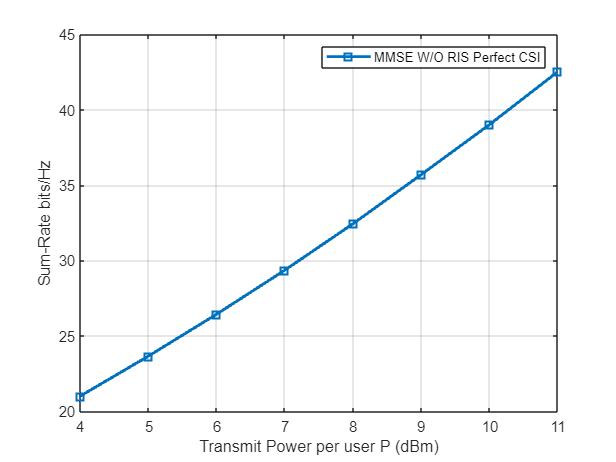

if ~useParallel
    close(f);
end

generatePlots4(methods, Pw_user_dBm,BerVec,RsumVec,0)

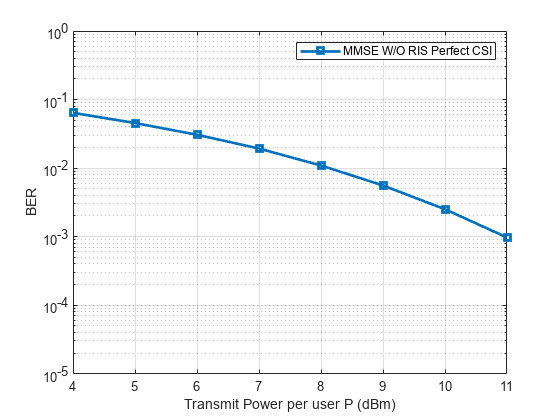

ylim([0.99e-5 1])